## load

clear all
filenameImagesTrain = 'train-images-idx3-ubyte';
filenameLabelsTrain = 'train-labels-idx1-ubyte';
filenameImagesTest = 't10k-images-idx3-ubyte';
filenameLabelsTest = 't10k-labels-idx1-ubyte';

XTrain_all = processImagesMNIST(filenameImagesTrain);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain_all = processLabelsMNIST(filenameLabelsTrain);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest_all= processImagesMNIST(filenameImagesTest);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest_all = processLabelsMNIST(filenameLabelsTest);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


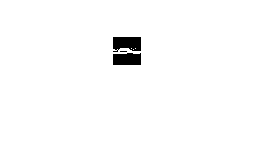

% Select label 5 and 7
XTrain = XTrain_all(YTrain_all==5|YTrain_all==7,:);
YTrain = YTrain_all(YTrain_all==5|YTrain_all==7,:);
XTest = XTest_all(YTest_all==5|YTest_all==7,:);
YTest = YTest_all(YTest_all==5|YTest_all==7,:);
YTest(YTest==5)=1;
YTrain(YTrain==5)=1;
YTest(YTest==7)=0;
YTrain(YTrain==7)=0;
test = XTest(1,:)';
test=reshape(test.*255,[28,28]);
imshow(test')

disp(YTest(1,:))

     1




clearvars -except XTrain YTrain XTest YTest

## First: Logistic Regression

Logistic regresssion in matlab doesn't have $C$, but using /lamda infront of the regularizaiton term.

%% LR 
lamba = [1e-16,1e-15,1e-14,1e-13,1e-12,1e-11,1e-10, 1e-9,1e-8,1e-7,1e-6, 1e-5, 1e-4, 1e-3, 1e-2,0.05, 1e-1, 1, 1e1, 1e2, 1e3]

lamba = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0010    0.0100    0.1000    1.0000


mdl = fitclinear(XTrain, YTrain,"Learner","logistic","Regularization","lasso", "Lambda",lamba,"Solver","sgd");
Label = predict(mdl,XTest);
accuracy = sum(Label == YTest)/length(YTest)
Label_train = predict(mdl,XTrain);
accuracy_train=sum(Label == Label_train)/length(YTrain)

% plot
Label_train = predict(mdl,XTrain);
accuracy_train=sum(Label_train == YTrain)/length(YTrain)

accuracy_train =     0.9529    0.9470    0.9549    0.9544    0.9515    0.9525    0.9540    0.9542    0.9540    0.9513    0.9513    0.9498    0.9515    0.9446    0.8919    0.6970    0.5000    0.5000    0.5000    0.5000    0.5000


pp=plot([1:length(lamba)],accuracy,[1:length(lamba)],accuracy_train,'linewidth',2)

pp =   2×1 Line array:

  Line
  Line


hold on
grid on 
xlabel('index')
ylabel('Accuracy')
xlim([0,length(lamba)])
ylim([0.45,1])


[m,idx]= max(accuracy)

m = 0.9560

idx = 6


plot(idx,m,'r*')
formatSpec = 'Higest accurcy: %.4f, \n\rwith a \\lambda of %.0e';
str = sprintf(formatSpec,m,lamba(idx))

str =     'Higest accurcy: 0.9560, 
     
     with a \lambda of 1e-11'


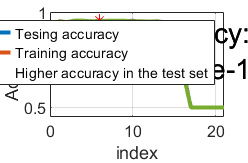


text(1,0.8,str,'FontSize',14)
legend('Tesing accuracy','Training accuracy','Higher accuracy in the test set')
hold off

## Second: SVM: [cjlin1/libsvm (github.com)](https://github.com/cjlin1/libsvm)


%% SVM
% C-SVM, linear
C = [1e-16,1e-15,1e-14,1e-13,1e-12,1e-11,1e-10, 1e-9,1e-8,1e-7,1e-6, 1e-5, 1e-4, 1e-3, 1e-2, 1e-1, 1, 1e1, 1e2, 1e3, 1e4, 1e5];
accuracies = zeros(size(C));
traing_times = zeros(size(C));
models = {};
for i = 1:length(C)
    disp(C(i))
    tic
    model = svmtrain(YTrain,XTrain,['-s 0 -t 0 -c ', convertStringsToChars(string(C(i)))]);
    traing_times(i) = toc;
    [predicted_label, accuracy, dec_values_L] = svmpredict(YTest, XTest,model);
    accuracies(i) = accuracy(1);
    models{i} = model;  
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
   1.0000e-16

   1.0000e-15

   1.0000e-14

   1.0000e-13

.....
*.*
optimization finished, #iter = 6000
nu = 1.000000
obj = -0.000000, rho = 0.000000
nSV = 12000, nBSV = 12000
Total nSV = 12000
.....
*.*
optimization finished, #iter = 6000
nu = 1.000000
obj = -0.000000, rho = 0.000000
nSV = 12000, nBSV = 12000
Total nSV = 12000
.....
*.*
optimization finished, #iter = 6000
nu = 1.000000
obj = -0.000000, rho = 0.000000
nSV = 12000, nBSV = 12000
Total nSV = 12000
.....
*.*
optimization finished, #iter = 6000
nu = 1.000000
obj = -0.000000, rho = 0.000000
nSV = 12000, nBSV = 12000
Total nSV = 12000
Accuracy = 85.95% (1719/2000) (classification)
Accuracy = 85.95% (1719/2000) (classification)
Accuracy = 85.95% (1719/2000) (classification)
A

accuracies_in_train = zeros(size(C));

parfor i=1:length(models)
    model = models{i};
    [predicted_label, accuracy, dec_values_L] = svmpredict(YTrain,XTrain,model);
    accuracies_in_train(i)=accuracy;
end
save()

plot(accuracies)
hold on
plot(accuracies_in_train);
hold off
plot(traing_times)